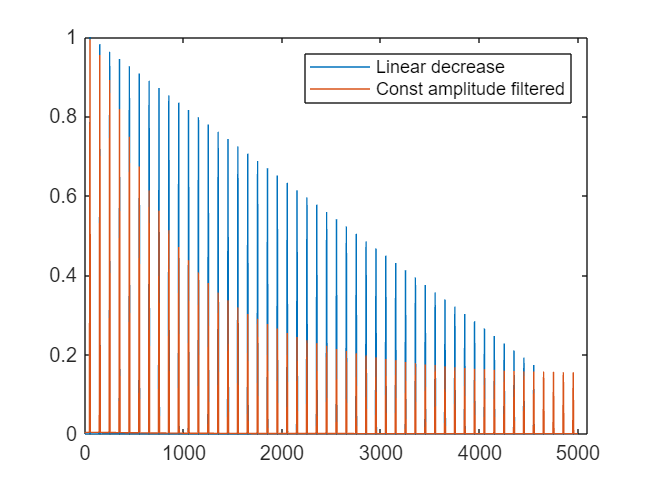

clear all

% Generating multisine
Nfreq = 50;
dfreq = 10;
maxFreq = 5000;
minFreq = 50;
fi = minFreq:((maxFreq-2*minFreq)/(Nfreq-1)):maxFreq;
dUi = (1-0.1)/(fi(end)-fi(1))*(fi(2)-fi(1))/2;
Ui = -(1-0.1)/(fi(end)-fi(1))*fi+1+dUi;
phase = randn(1,Nfreq);
fc = 500;

dt = 1/10000;
t = [0:dt:10/fi(1)-dt];

y_temp = 0;
y_temp_unfilt = 0;
for i = 1:Nfreq
    y_temp = y_temp + Ui(i)*sin(2*pi*fi(i)*t+2*pi*phase(i));
    y_temp_unfilt = y_temp_unfilt + sin(2*pi*fi(i)*t+2*pi*phase(i));
end

wc = 2*pi*fc;
G = tf(1,[1/wc 1]);
yfilt = lsim(G,y_temp_unfilt,t);

% Spectre of generated signal
Y = abs(fft(y_temp))/length(t);
Yfilt = abs(fft(yfilt))/length(t);
df = (1/(length(t)*dt));
f = [0:df:(1/dt)-df];
f_egy = f(1:end/2);
Y(2:end) = 2*Y(2:end);
Y_egy = Y(1:end/2);
Yfilt(2:end) = 2*Yfilt(2:end);
Yfilt_egy = Yfilt(1:end/2);
plot(f_egy,Y_egy)
hold on
plot(f_egy,Yfilt_egy)
hold off
xlim([0,5100])
legend('Linear decrease','Const amplitude filtered')

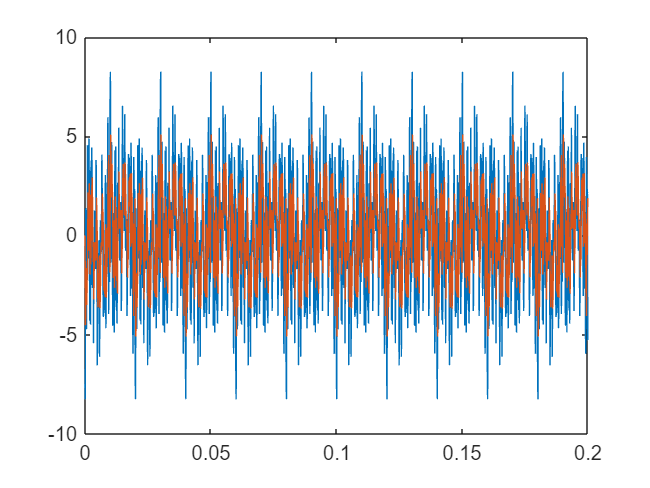


plot(t,y_temp)
hold on
plot(t,yfilt)
hold off

N = 16;
y = ((y_temp/(max(y_temp)-min(y_temp)+1)*2)+1)/2 % XD OK

y =     0.3829    0.3273    0.4250    0.4687    0.4532    0.5272    0.4264    0.4417    0.6026    0.5810    0.6852    0.5567    0.2490    0.3570    0.6687    0.7689    0.6811    0.6867    0.6282    0.6407    0.6058    0.7308    0.5271    0.5024    0.7987    0.5850    0.4488    0.3382    0.6297    0.7213    0.5659    0.4451    0.4274    0.3478    0.4788    0.6130    0.5587    0.7752    0.7721    0.5380    0.5429    0.5858    0.4758    0.5457    0.4755    0.4067    0.4565    0.3493    0.3864    0.4232


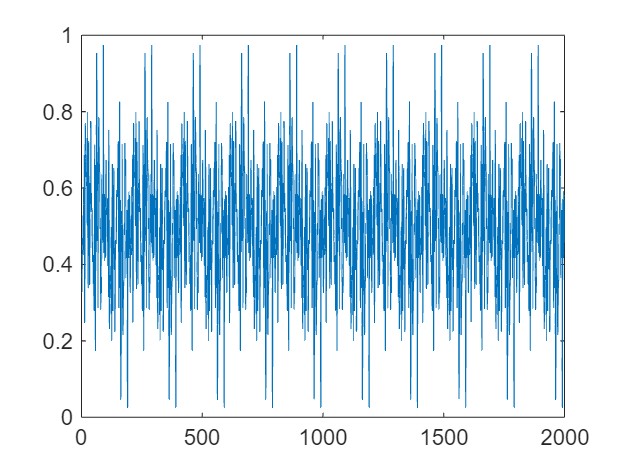

plot(y)

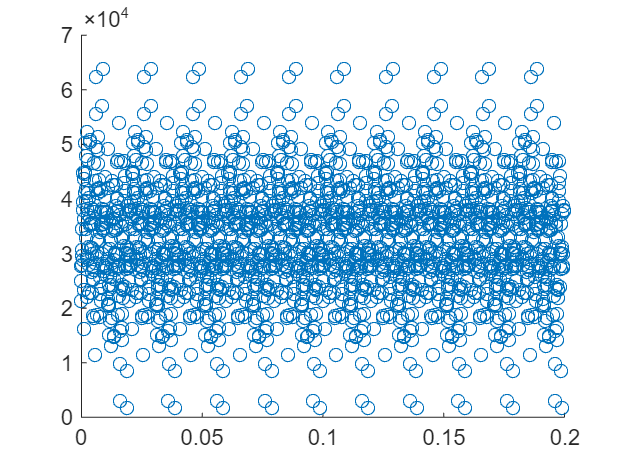

y_hex = floor(y*(2^N-1));
scatter(t,y_hex)


hex_sine = dec2hex(y_hex)

hex_sine = 2000×4 char array
    '6202'
    '53C6'
    '6CCD'
    '77FB'
    '7405'
    '86F7'
    '6D27'
    '7115'
    '9A41'
    '94BD'
    'AF6B'
    '8E86'
    '3FBA'
    '5B63'
    'AB2F'
    'C4D3'
    'AE5B'
    'AFCC'
    'A0D3'
    'A407'
    '9B14'
    'BB14'
    '86F0'
    '809D'
    'CC76'
    '95BF'
    '72E2'
    '5693'
    'A132'
    'B8A4'
    '90E0'
    '71F3'
    '6D69'
    '590B'
    '7A91'
    '9CF0'
    '8F07'
    'C673'
    'C5A6'
    '89B9'
    '8AFA'
    '95F9'
    '79CC'
    '8BB5'
    '79BA'
    '681F'
    '74DE'
    '596D'
    '62E9'
    '6C56'
    '637C'
    '48C5'
    '478C'
    '8AEF'
    'B674'
    '9490'
    '6990'
    '2CC1'
    '9377'
    'A91F'
    '6ED3'
    'C1EB'
    'F3E7'
    'D9C2'
    'A2DB'
    '766E'
    '7F55'
    '4931'
    '739B'
    'A0B7'
    'BF8F'
    'C8AA'
    'B59D'
    'AA17'
    'A4CA'
    'A3DB'
    '7E49'
    '853B'
    '64DF'
    '4851'
    '5847'
    '5DBD'
    '534F'
    '9385'
    'A28B'
    '8A3C'
    '9533'
    '8A89'
   

MSB = bitshift(y_hex,-8) 

MSB =     98    83   108   119   116   134   109   113   154   148   175   142    63    91   171   196   174   175   160   164   155   187   134   128   204   149   114    86   161   184   144   113   109    89   122   156   143   198   197   137   138   149   121   139   121   104   116    89    98   108


msb_sine = "0x"+string(dec2hex(MSB))

msb_sine = 2000×1 string array
    "0x62"
    "0x53"
    "0x6C"
    "0x77"
    "0x74"
    "0x86"
    "0x6D"
    "0x71"
    "0x9A"
    "0x94"
    "0xAF"
    "0x8E"
    "0x3F"
    "0x5B"
    "0xAB"
    "0xC4"
    "0xAE"
    "0xAF"
    "0xA0"
    "0xA4"
    "0x9B"
    "0xBB"
    "0x86"
    "0x80"
    "0xCC"
    "0x95"
    "0x72"
    "0x56"
    "0xA1"
    "0xB8"


lsb_sine = "0x"+string(dec2hex(y_hex-MSB*2^8))

lsb_sine = 2000×1 string array
    "0x02"
    "0xC6"
    "0xCD"
    "0xFB"
    "0x05"
    "0xF7"
    "0x27"
    "0x15"
    "0x41"
    "0xBD"
    "0x6B"
    "0x86"
    "0xBA"
    "0x63"
    "0x2F"
    "0xD3"
    "0x5B"
    "0xCC"
    "0xD3"
    "0x07"
    "0x14"
    "0x14"
    "0xF0"
    "0x9D"
    "0x76"
    "0xBF"
    "0xE2"
    "0x93"
    "0x32"
    "0xA4"



mcu_sin = [msb_sine,lsb_sine]

mcu_sin = 2000×2 string array
    "0x62"    "0x02"
    "0x53"    "0xC6"
    "0x6C"    "0xCD"
    "0x77"    "0xFB"
    "0x74"    "0x05"
    "0x86"    "0xF7"
    "0x6D"    "0x27"
    "0x71"    "0x15"
    "0x9A"    "0x41"
    "0x94"    "0xBD"
    "0xAF"    "0x6B"
    "0x8E"    "0x86"
    "0x3F"    "0xBA"
    "0x5B"    "0x63"
    "0xAB"    "0x2F"
    "0xC4"    "0xD3"
    "0xAE"    "0x5B"
    "0xAF"    "0xCC"
    "0xA0"    "0xD3"
    "0xA4"    "0x07"
    "0x9B"    "0x14"
    "0xBB"    "0x14"
    "0x86"    "0xF0"
    "0x80"    "0x9D"
    "0xCC"    "0x76"
    "0x95"    "0xBF"
    "0x72"    "0xE2"
    "0x56"    "0x93"
    "0xA1"    "0x32"
    "0xB8"    "0xA4"


mcu_sin_reshaped = reshape(mcu_sin',1,[])

mcu_sin_reshaped = 1×4000 string array
  Columns 1 through 3276

    "0x62"    "0x02"    "0x53"    "0xC6"    "0x6C"    "0xCD"    "0x77"    "0xFB"    "0x74"    "0x05"    "0x86"    "0xF7"    "0x6D"    "0x27"    "0x71"    "0x15"    "0x9A"    "0x41"    "0x94"    "0xBD"    "0xAF"    "0x6B"    "0x8E"    "0x86"    "0x3F"    "0xBA"    "0x5B"    "0x63"    "0xAB"    "0x2F"    "0xC4"    "0xD3"    "0xAE"    "0x5B"    "0xAF"    "0xCC"    "0xA0"    "0xD3"    "0xA4"    "0x07"    "0x9B"    "0x14"    "0xBB"    "0x14"    "0x86"    "0xF0"    "0x80"    "0x9D"    "0xCC"    "0x76"    "0x95"    "0xBF"    "0x72"    "0xE2"    "0x56"    "0x93"    "0xA1"    "0x32"    "0xB8"    "0xA4"    "0x90"    "0xE0"    "0x71"    "0xF3"    "0x6D"    "0x69"    "0x59"    "0x0B"    "0x7A"    "0x91"    "0x9C"    "0xF0"    "0x8F"    "0x07"    "0xC6"    "0x73"    "0xC5"    "0xA6"    "0x89"    "0xB9"    "0x8A"    "0xFA"    "0x95"    "0xF9"    "0x79"    "0xCC"    "0x8B"    "0xB5"    "0x79"    "0xBA"    "0x68"    "0x1F"    "0x74"    "


%writing to file for MCU
% folder = "C:\Users\Peter\STM32CubeIDE\workspace_1.12.0\RedPill_DAC_SPI_MultiSin_FFT\Core\Src\";
% fid = fopen(folder+"dacMultiSine.txt",'wt');
% fprintf(fid,'%s,', mcu_sin_reshaped{1:end-1});
% fprintf(fid,'%s', mcu_sin_reshaped{end});
% fclose(fid);